# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 9

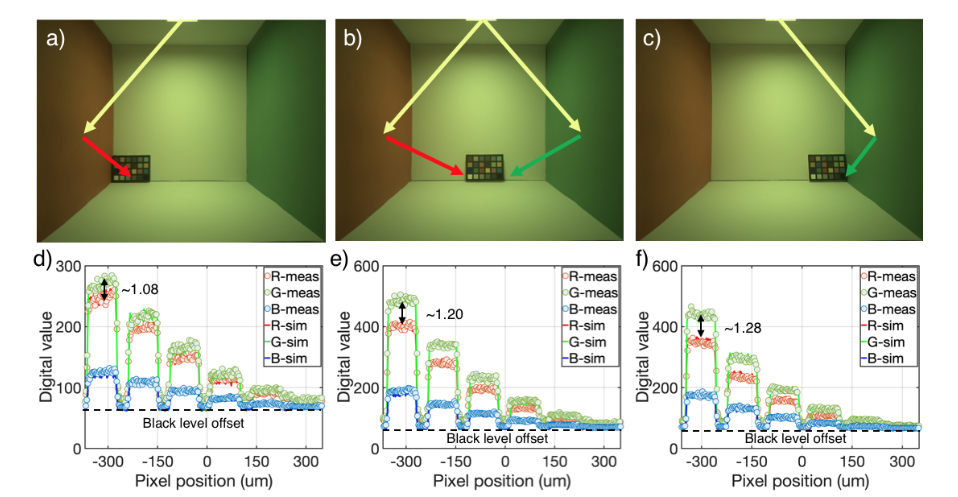

Fig. 9. Comparisons of simulated and measured digital values in the complex scene including inter-reflections. (a-c) Acquired images of an MCC at three different positions along the rear wall. The arrows show the likely paths for inter-reflections from the light source off the nearby walls onto the MCC. The white rectangle highlights the position of the achromatic patches on the MCC. (d-f) The digital values from the Google Pixel 4a images (dashed lines) are compared with the simulated values (solid lines). See text for details

**Download**

Prior to running these scripts, please download the data we have prepared on the Stanford digital Repository at this URL

     [https://purl.stanford.edu/jz021qy7454](https://purl.stanford.edu/jz021qy7454) 

These are zip files that need to be uncompressed.  You may need to set the path correctly for your computer to read in the prepared files.

%%
ieInit;

%% Load the 3 rendered results.  These are the downloads mentioned above.
savePath = fullfile(cboxRootPath, 'local',...
                    'simulation', 'mcc_pos', 'oi');

load(fullfile(savePath, 'oiMCCLeft_8bounces.mat'), 'oiMCCLeft');
load(fullfile(savePath, 'oiMCCMid_8bounces.mat'), 'oiMCCMid');
load(fullfile(savePath, 'oiMCCRight_8bounces.mat'), 'oiMCCRight');

% Adjust illuminance
meanIlluLeft = oiGet(oiMCCLeft, 'mean illuminance');
oiMCCLeftAdj = oiSet(oiMCCLeft, 'mean illuminance', meanIlluLeft * 0.6131);
meanIlluMid = oiGet(oiMCCMid, 'mean illuminance');
oiMCCMidAdj = oiSet(oiMCCMid, 'mean illuminance', meanIlluMid * 0.7396);
meanIlluRight = oiGet(oiMCCRight, 'mean illuminance');
oiMCCRightAdj = oiSet(oiMCCRight, 'mean illuminance', meanIlluRight * 0.7183);

%% Load real sensor data
measPath = fullfile(cboxRootPath, 'data', 'measurement', 'mccpos');

% Middle
dngMiddle = 'IMG_20210105_163525.dng';
[sensorMMeas, infoMMeas, ipMMeas] = cbDNGRead(fullfile(measPath, 'middle',dngMiddle), 'demosaic', true);

% Left
dngLeft = 'IMG_20210105_163902.dng';
[sensorLMeas, infoLMeas, ipLMeas] = cbDNGRead(fullfile(measPath, 'left', dngLeft), 'demosaic', true);

% Right
dngRight = 'IMG_20210105_164410.dng';
[sensorRMeas, infoRMeas, ipRMeas] = cbDNGRead(fullfile(measPath, 'right', dngRight), 'demosaic', true);

% Crop Sensor data

% Left
rectLMeas = [1066        1787         530         388];
sensorLMeasCrp = sensorCrop(sensorLMeas, rectLMeas);

% Mid
rectMMeas = [1828        1824         480         323];
sensorMMeasCrp = sensorCrop(sensorMMeas, rectMMeas);

% Right
rectRMeas = [2406        1823         488         322];
sensorRMeasCrp = sensorCrop(sensorRMeas, rectRMeas);

% Preview image
mccMMeas = ipGet(ipMMeas, 'srgb');

mccLMeas = ipGet(ipLMeas, 'srgb');

mccRMeas = ipGet(ipRMeas, 'srgb');

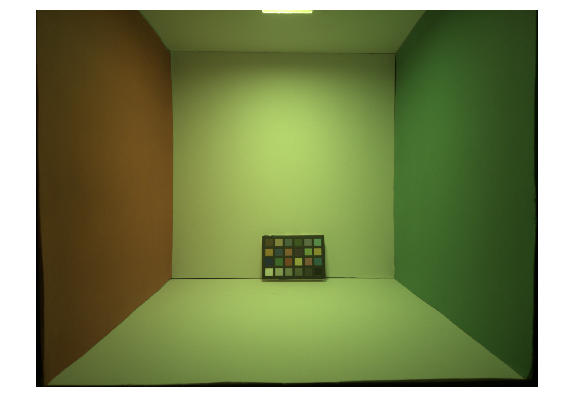

ieNewGraphWin; imshow(mccMMeas);

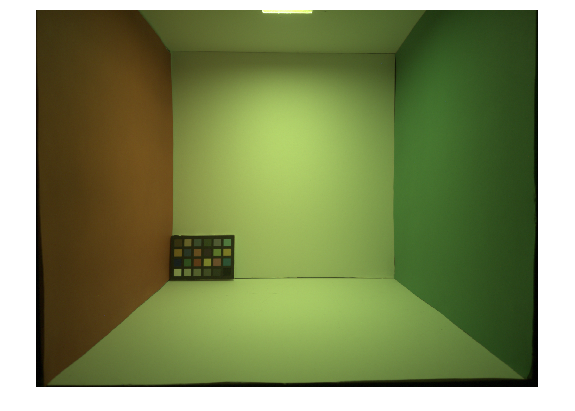

ieNewGraphWin; imshow(mccLMeas);

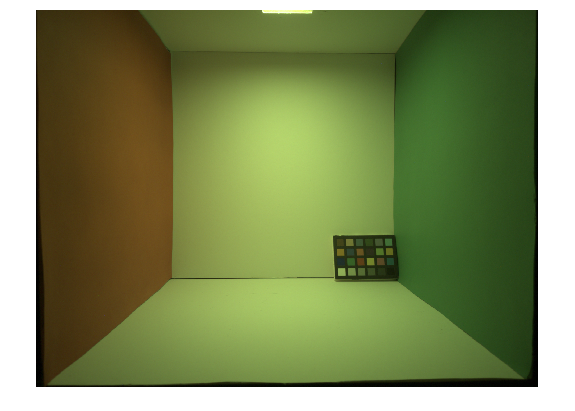

ieNewGraphWin; imshow(mccRMeas);

**Select region**

% Left
sensorLSim = sensorLMeas;
sensorLSim = cbSensorCompute(sensorLSim, oiMCCLeftAdj);
rectLSim = [1121        1822         537         351];
sensorLSimCrp = sensorCrop(sensorLSim, rectLSim);
% Middle
sensorMSim = sensorMMeas;
sensorMSim = cbSensorCompute(sensorMSim, oiMCCMidAdj);
rectMSim = [1756        1825         527         360];
sensorMSimCrp = sensorCrop(sensorMSim, rectMSim);
% Right
sensorRSim = sensorRMeas;
sensorRSim = cbSensorCompute(sensorRSim, oiMCCRightAdj);
rectRSim = [2373        1823         542         358];
sensorRSimCrp = sensorCrop(sensorRSim, rectRSim);

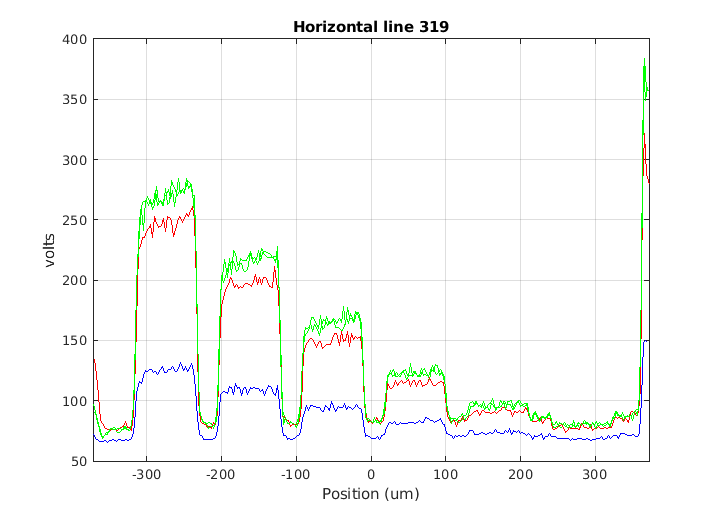

%% Analyze the result (Left)
hLineLMeas = 319;
lMeasData = sensorPlot(sensorLMeasCrp, 'dv hline', [1 hLineLMeas], 'two lines', true);

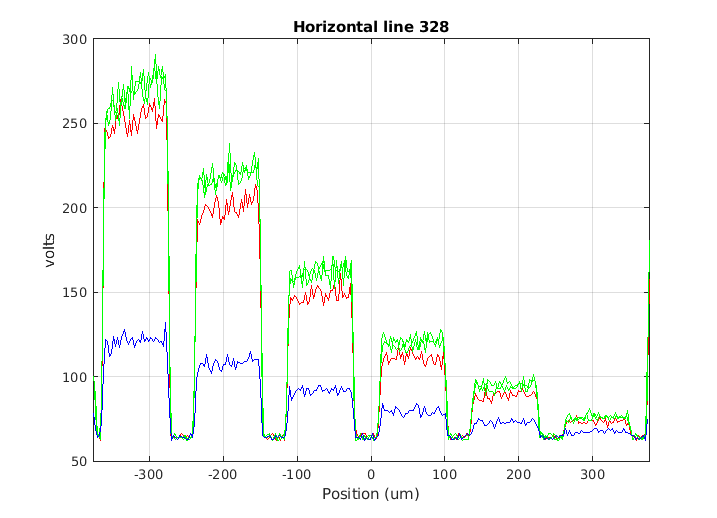


hLineMSim = 328;
lSimData = sensorPlot(sensorLSimCrp, 'dv hline', [1 hLineMSim], 'two lines', true);

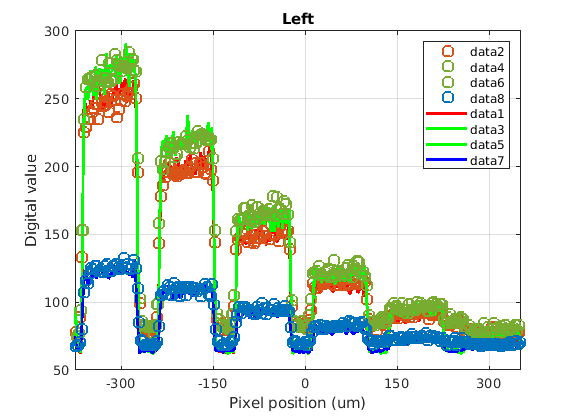


patternMeas = lMeasData.pixColor; patternSim = lSimData.pixColor;
t = 'Left';
cbPlotSensorData(lSimData, lMeasData, t, patternSim, patternMeas);
labels = get(legend(), 'String');
plots = flipud(get(gca, 'children'));
neworder = [2 4 6 8 1 3 5 7 ];
legend(plots(neworder), labels(neworder));
xlim([-375 350]); ylim([50 300]);
xticks([-300:150:300])

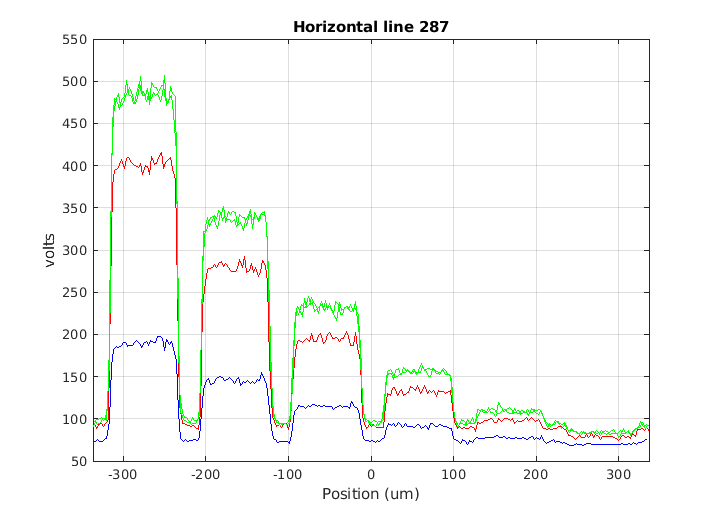


%% Analyze the result (Mid)
hLineMMeas = 287;
mMeasData = sensorPlot(sensorMMeasCrp, 'dv hline', [1 hLineMMeas], 'two lines', true);

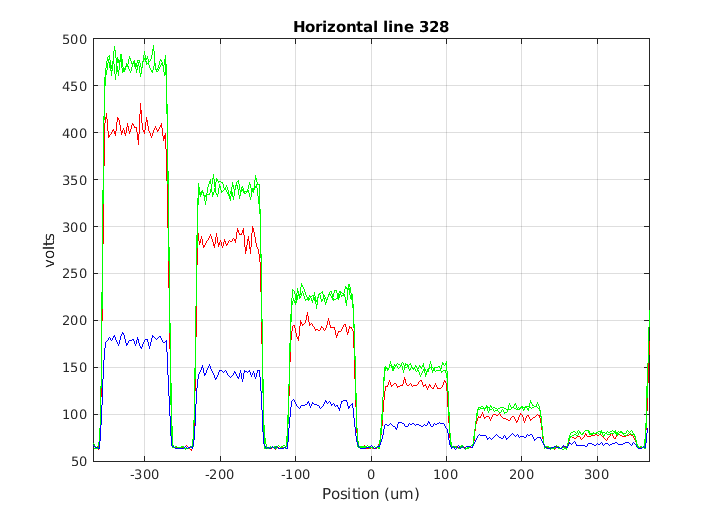


hLineMSim = 328;
mSimData = sensorPlot(sensorMSimCrp, 'dv hline', [1 hLineMSim], 'two lines', true);

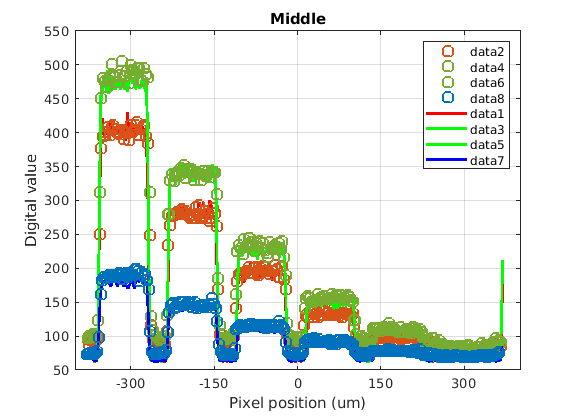


patternMeas = mMeasData.pixColor; patternSim = mSimData.pixColor;
t = 'Middle';
cbPlotSensorData(mSimData, mMeasData, t, patternSim, patternMeas);
labels = get(legend(), 'String');
plots = flipud(get(gca, 'children'));
neworder = [2 4 6 8 1 3 5 7 ];
legend(plots(neworder), labels(neworder))
xticks([-300:150:300])

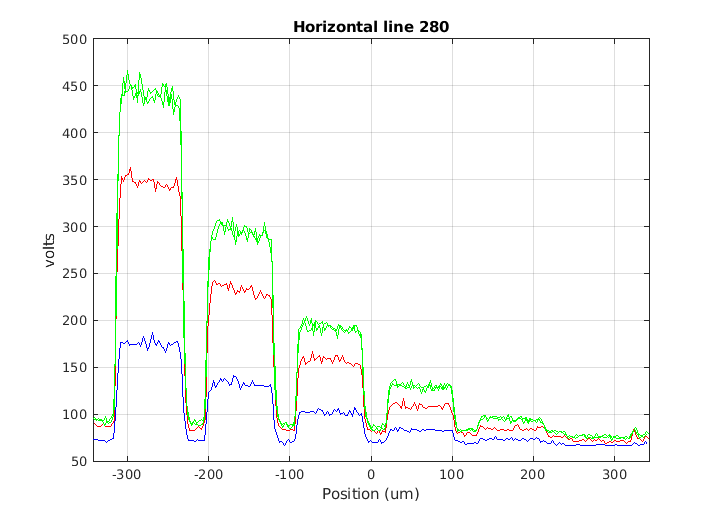


%% Analyze the result (Right)
hLineRMeas = 280;
rMeasData = sensorPlot(sensorRMeasCrp, 'dv hline', [1 hLineRMeas], 'two lines', true);

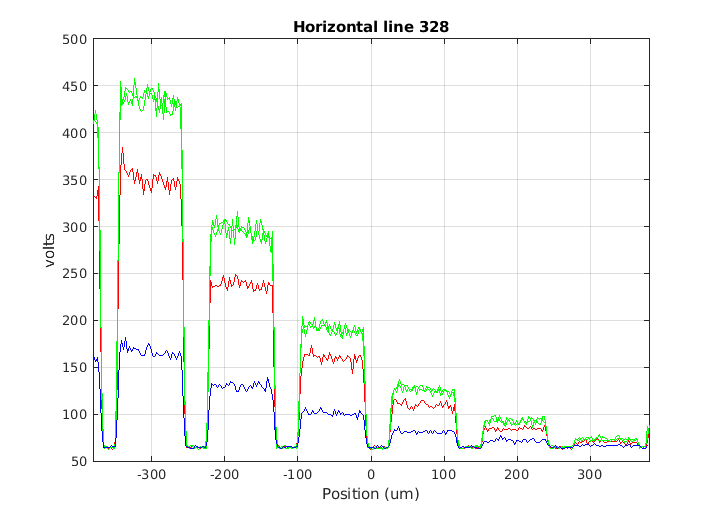


hLineRSim = 328;
rSimData = sensorPlot(sensorRSimCrp, 'dv hline', [1 hLineRSim], 'two lines', true);


patternMeas = rMeasData.pixColor; patternSim = rSimData.pixColor;
t = 'Right';
cbPlotSensorData(rSimData, rMeasData, t, patternSim, patternMeas);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 27183.617396 



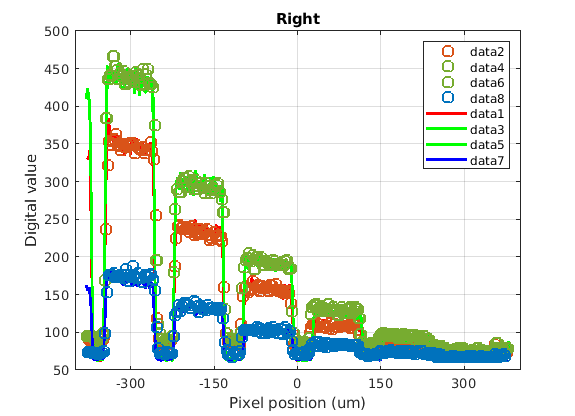

labels = get(legend(), 'String');
plots = flipud(get(gca, 'children'));
neworder = [2 4 6 8 1 3 5 7 ];
legend(plots(neworder), labels(neworder))
xticks([-300:150:300])

%% To reproduce the render optical image results
% Note the rendered OIs are not final sensor data, so the appearance should
% be different from the real data which are real sensor data.
% Basic parameter initialization
from = [0 0.10 -0.385];
to = [0 0.125, 0.6];

% Left
% Original quality: [252 189] * 16;
resolution = [252 189];
nRaysPerPixel = 128;
nBounces = 8;

label = 'Left';
oiMCCLeftFast = cbOISim('from', from,...
                'to', to,...
                'resolution', resolution,...
                'n rays per pixel', nRaysPerPixel,... 
                'nbounces', nBounces,...
                'label', label,...
                'filmdistance', 0.49234,...
                'remove cube', true,...
                'add bunny', false,...
                'add mcc', true,...
                'mcc trans', [-0.1 0 0]);

Read 1 materials.
Read 1 textures.
***Scene parsed.

Scene materials: CornellBoxReference
-------------------------------
             name        type
         ____________    ____

    1    BackWall        uber
    2    BottomWall      uber
    3    CubeLarge       uber
    4    CubeSmall       uber
    5    LeftWall        uber
    6    RightWall       uber
    7    ShieldMat       uber
    8    TopWall         uber
    9    areaLightMat    uber

-------------------------------
Assigned reflectance to: ShieldMat
Assigned reflectance to: LeftWall
Assigned reflectance to: RightWall
Assigned reflectance to: BackWall
Assigned reflectance to: TopWall
Assigned reflectance to: BottomWall
Assigned reflectance to: CubeLarge
Assigned reflectance to: CubeSmall


camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


Overwriting PBRT file /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/home/zhenglyu/git/iset3d/local/CornellBoxReference" --volume="/home/zhenglyu/git/iset3d/local/CornellBoxReference":"/home/zhenglyu/git/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /home/zhenglyu/git/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  13.0 sec ***

  Reading image h=189 x w=252 x 31 spectral planes.


oiWindow(oiMCCLeftFast); 

% Middle
label = 'Left';
oiMCCMidFast = cbOISim('from', from,...
                'to', to,...
                'resolution', resolution,...
                'n rays per pixel', nRaysPerPixel,... 
                'nbounces', nBounces,...
                'label', label,...
                'filmdistance', 0.49234,...
                'remove cube', true,...
                'add bunny', false,...
                'add mcc', true);

Read 1 materials.
Read 1 textures.
***Scene parsed.

Scene materials: CornellBoxReference
-------------------------------
             name        type
         ____________    ____

    1    BackWall        uber
    2    BottomWall      uber
    3    CubeLarge       uber
    4    CubeSmall       uber
    5    LeftWall        uber
    6    RightWall       uber
    7    ShieldMat       uber
    8    TopWall         uber
    9    areaLightMat    uber

-------------------------------
Assigned reflectance to: ShieldMat
Assigned reflectance to: LeftWall
Assigned reflectance to: RightWall
Assigned reflectance to: BackWall
Assigned reflectance to: TopWall
Assigned reflectance to: BottomWall
Assigned reflectance to: CubeLarge
Assigned reflectance to: CubeSmall


camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


Overwriting PBRT file /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/home/zhenglyu/git/iset3d/local/CornellBoxReference" --volume="/home/zhenglyu/git/iset3d/local/CornellBoxReference":"/home/zhenglyu/git/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /home/zhenglyu/git/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  12.8 sec ***

  Reading image h=189 x w=252 x 31 spectral planes.


oiWindow(oiMCCMidFast); 

% Right
label = 'Right';
oiMCCRightFast = cbOISim('from', from,...
                'to', to,...
                'resolution', resolution,...
                'n rays per pixel', nRaysPerPixel,... 
                'nbounces', nBounces,...
                'label', label,...
                'filmdistance', 0.49234,...
                'remove cube', true,...
                'add bunny', false,...
                'add mcc', true,...
                'mcc trans', [0.1 0 0]);

Read 1 materials.
Read 1 textures.
***Scene parsed.

Scene materials: CornellBoxReference
-------------------------------
             name        type
         ____________    ____

    1    BackWall        uber
    2    BottomWall      uber
    3    CubeLarge       uber
    4    CubeSmall       uber
    5    LeftWall        uber
    6    RightWall       uber
    7    ShieldMat       uber
    8    TopWall         uber
    9    areaLightMat    uber

-------------------------------
Assigned reflectance to: ShieldMat
Assigned reflectance to: LeftWall
Assigned reflectance to: RightWall
Assigned reflectance to: BackWall
Assigned reflectance to: TopWall
Assigned reflectance to: BottomWall
Assigned reflectance to: CubeLarge
Assigned reflectance to: CubeSmall


camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


Overwriting PBRT file /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/home/zhenglyu/git/iset3d/local/CornellBoxReference" --volume="/home/zhenglyu/git/iset3d/local/CornellBoxReference":"/home/zhenglyu/git/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /home/zhenglyu/git/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  12.8 sec ***

  Reading image h=189 x w=252 x 31 spectral planes.


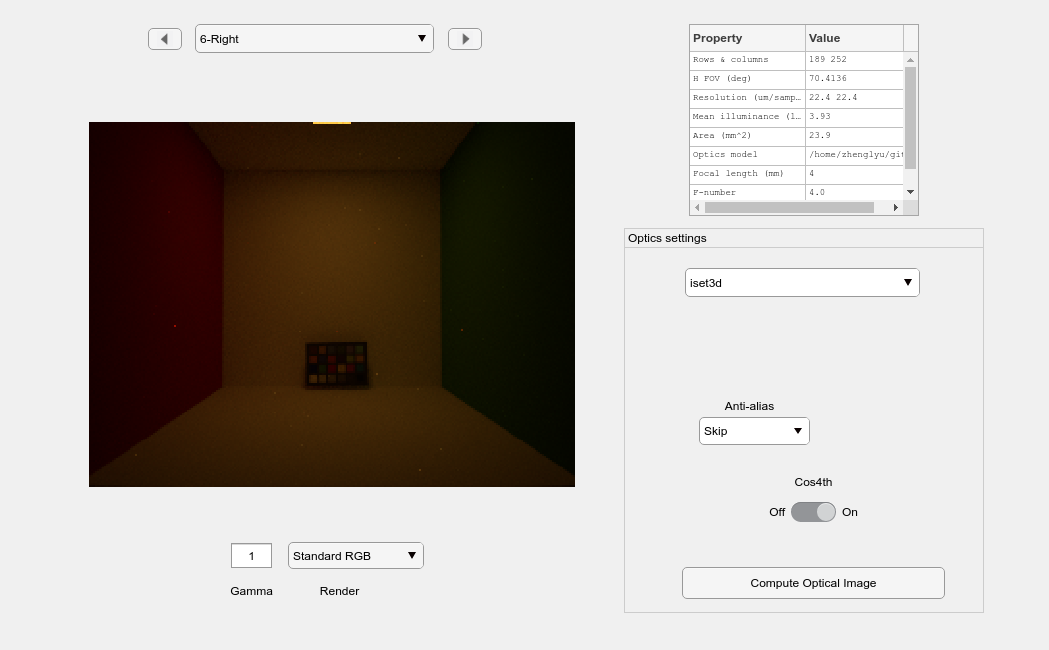

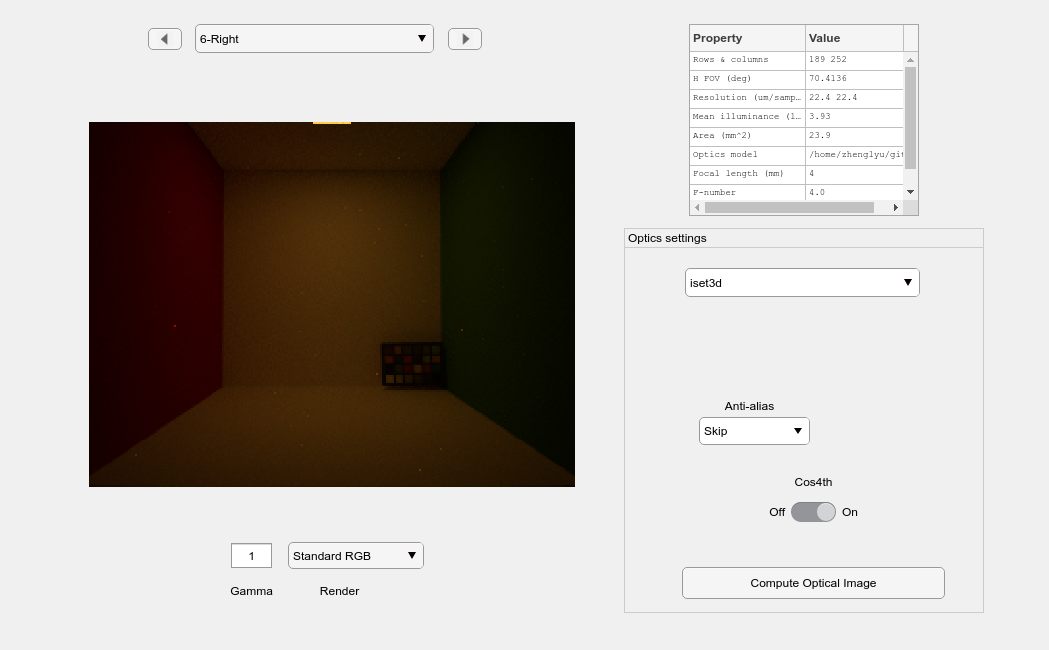

oiWindow(oiMCCRightFast);